# ALL - ROBUSTNESS - DISTURBANCE

clear;

%params
tar = 3;

%mpcpd params
pred_horizon = 100;
cont_update = 10;
g = [1; 1; 1; 50; 50; 50];

## realvleospacecraft0 ldist

%clean
if (exist('loop_real', 'var'))
    if ~(strcmp(loop_real, 'realvleospacecraft0_mpcpd'))
        set_param(loop_real, 'FastRestart', 'off');
        set_param(loop_model, 'FastRestart', 'off');
        close_system(loop_real);
        close_system(loop_model);
    end
end
clearvars -except tar pred_horizon cont_update g;

%models
loop_real = 'realvleospacecraft0_mpcpd';
loop_model = 'realvleospacecraft0_nodist_mpcpd_model';
sc_real = 'realvleospacecraft0';
sc_model = 'realvleospacecraft0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 200;

%disturbances
disturbances;

### b 

1_realvleospacecraft0_ldist_b

%info
filename = '1_realvleospacecraft0_ldist_b';
info = 'b: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2)';

%params
costfunction = 1;

%disturbance
tau_dist_ser = light_tau_dist_ser;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;

prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot light_tau_dist_ser;

### c

1_realvleospacecraft0_ldist_c

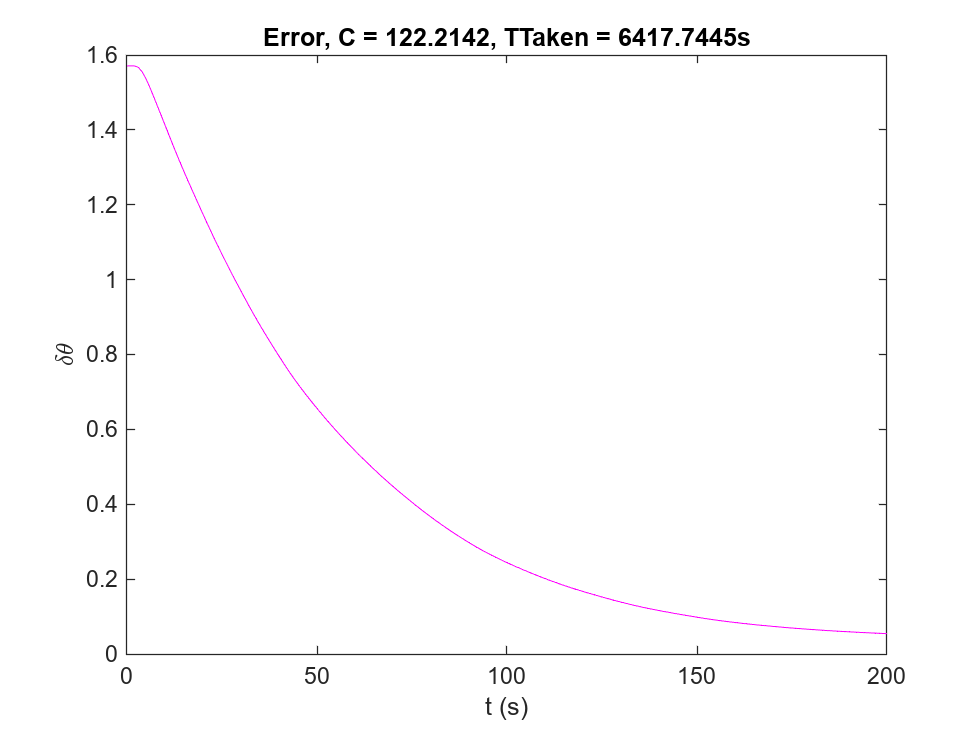

%info
filename = '1_realvleospacecraft0_ldist_c';
info = 'c: 100 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 2e-4w_rw^2 + 0.01k^2)';

%params
costfunction = 4;

%disturbance
tau_dist_ser = light_tau_dist_ser;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;
prepvisualise;


%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot light_tau_dist_ser;

## realvleospacecraft0 hdist

%clean
if (exist('loop_real', 'var'))
    if ~(strcmp(loop_real, 'realvleospacecraft0_mpcpd'))
        set_param(loop_real, 'FastRestart', 'off');
        set_param(loop_model, 'FastRestart', 'off');
        close_system(loop_real);
        close_system(loop_model);
    end
end
clearvars -except tar pred_horizon cont_update g;

%models
loop_real = 'realvleospacecraft0_mpcpd';
loop_model = 'realvleospacecraft0_nodist_mpcpd_model';
sc_real = 'realvleospacecraft0';
sc_model = 'realvleospacecraft0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 200;

%disturbances
disturbances;

### b 

1_realvleospacecraft0_hdist_b

%info
filename = '1_realvleospacecraft0_hdist_b';
info = 'b: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2)';

%params
costfunction = 1;

%disturbance
tau_dist_ser = heavy_tau_dist_ser;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot heavy_tau_dist_ser;

### c

1_realvleospacecraft0_ldist_c

%info
filename = '1_realvleospacecraft0_hdist_c';
info = 'c: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 2e-4w_rw^2 + 0.01k^2)';

%params
costfunction = 4;

%disturbance
tau_dist_ser = heavy_tau_dist_ser;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot heavy_tau_dist_ser;